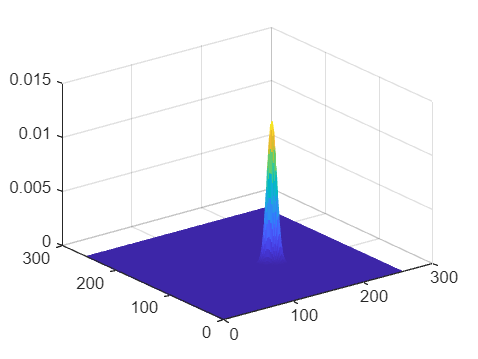

clear all; close all;

%imtool("model_skory.bmp");
model = createSkinModel('model_skory.bmp');
figure;
mesh(model);

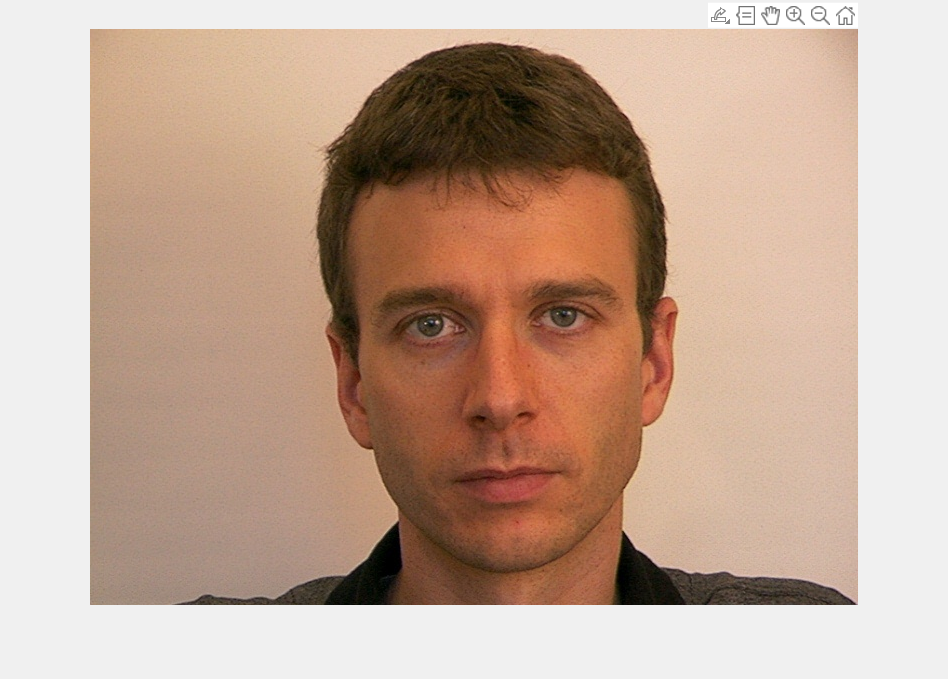


kolor_skory2

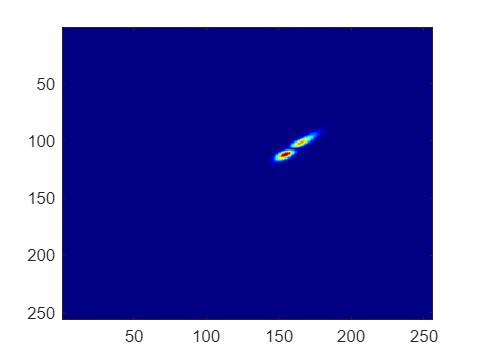

%figure;imagesc(model);colormap(jet);
%figure;imagesc(model2);colormap(jet);
figure;imagesc(abs(model-model2));colormap(jet);

Detekcja twarzy

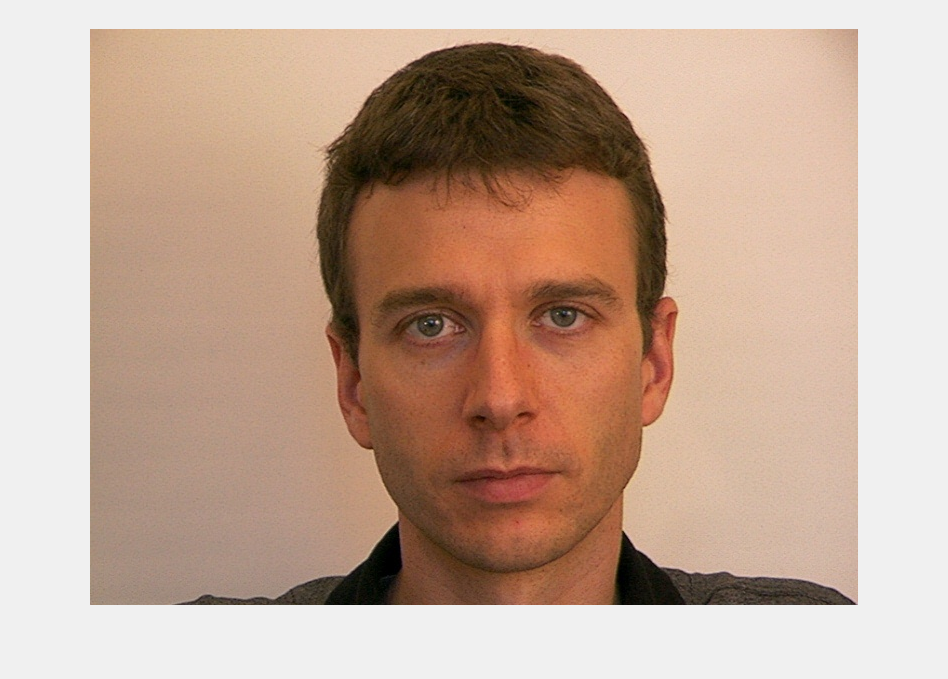

ans =            3           1           1       97998           1           3          27           5           8           7        2055           6           3          44           4           4           4           2           9          22           1          16         176          13          33           1


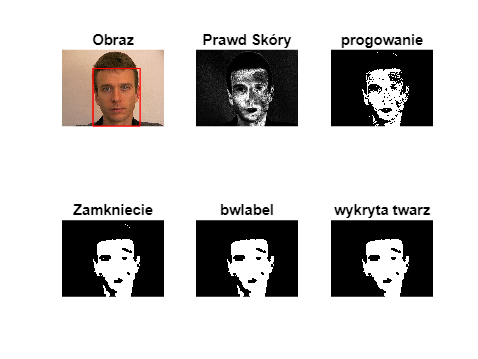

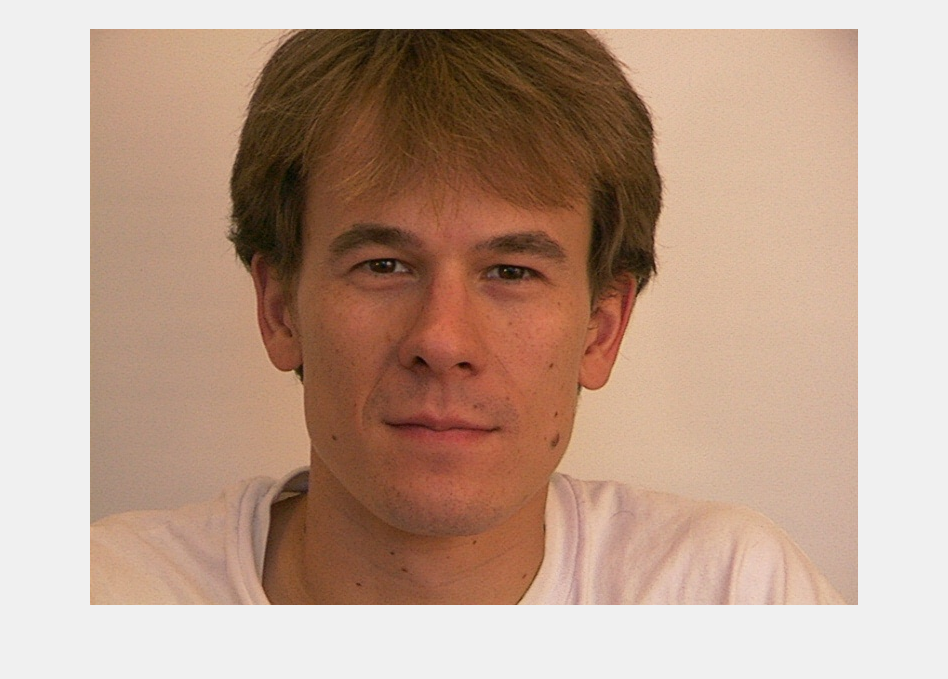

ans =           13           1           5           5          41           3           4           3           1           5           1          28           3          39           1           1           1          29          17           1          14           2           1      108679           1           2           4           3           1           5           2           8         182           3          70           1           1           1          29        3724           1           7          18          27          27          21           1           4           5          25


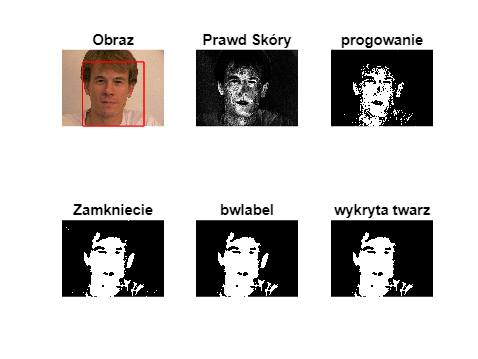

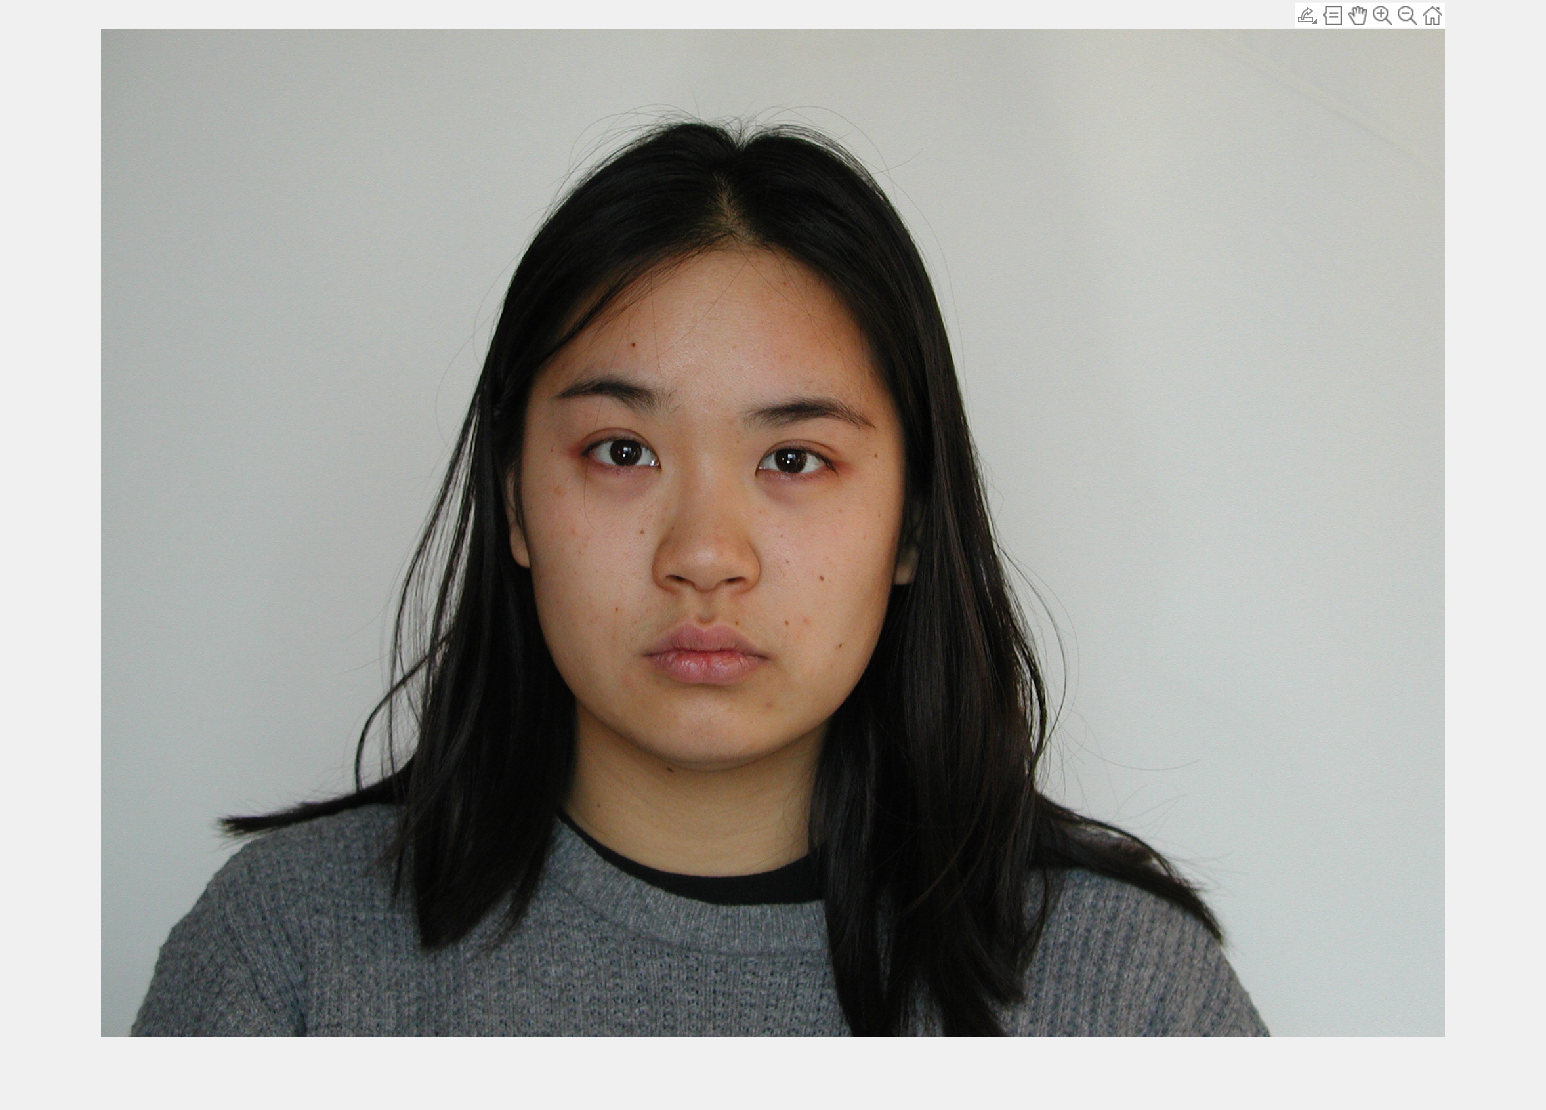

ans =            4      383412          52           4          64          17           2          86           1          37           3


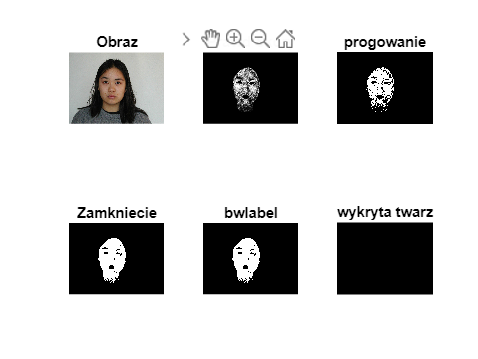

Index exceeds the number of array elements. Index must not exceed 1.

addpath('BazaObrazow');
testowy1 = imread('testowy_0_0000.jpeg');
testowy2 = imread('testowy_1_0000.jpeg');
testowy3 = imread('testowy_2_0000.jpeg');

testowe = {testowy1, testowy2, testowy3};

for testowi = testowe

    testowy = testowi{1, 1};
    Copy_of_kolor_skory2;
    figure, subplot(2,3,1), imshow(testowy), title("Obraz");
    %szary = probabilityIM(testowy,model);
    %subplot(2,3,2), imshow(szary,[])
    %colormap(gray);
    szary = probabilityIM(testowy,model2);
    subplot(2,3,2), imshow(szary,[]), title("Prawd Skóry");
    colormap(gray);
    
    %edit probabilityIM
    level = max(max(szary))/4;
    binarny = im2bw(szary, level);
    subplot(2,3,3), imshow(binarny), title("progowanie");
    
    se = strel('disk', 8);% dobierz parametry element strukturalnego
    zamkniety = imclose(binarny, se);
    subplot(2,3,4), imshow(zamkniety), title("Zamkniecie");
    
    label1 = bwlabel(zamkniety);
    res = regionprops(label1);
    [res.Area]
    wyczyszczony = bwareaopen(zamkniety,400); % dobierz parametry
    subplot(2,3,5), imshow(wyczyszczony), title("bwlabel");
    
    [x1, x2, twarz] = szukaj_twarz(wyczyszczony);
    subplot(2,3,6), imshow(twarz), title("wykryta twarz");
    %dodatkowa wizualizacja
    subplot(2,3,1)
    pos=[x1(2) x1(1) x2(2)-x1(2) x2(1)-x1(1)];
    hold on;rectangle('Position',pos,'EdgeColor','red'); hold off

end %for testowy = testowe

Detekcja twarzy z wykorzystaniem kaskad Haara

testowy = imread("testowy_0_0000.jpeg");

Unable to resolve the name 'testowy_0_0000.jpeg'.

faceDetector = vision.CascadeObjectDetector();
bbox = step(faceDetector, testowy)
Out = insertObjectAnnotation(testowy,'rectangle',bbox,'Twarz');
figure, imshow(Out), title('Wykryta twarz');